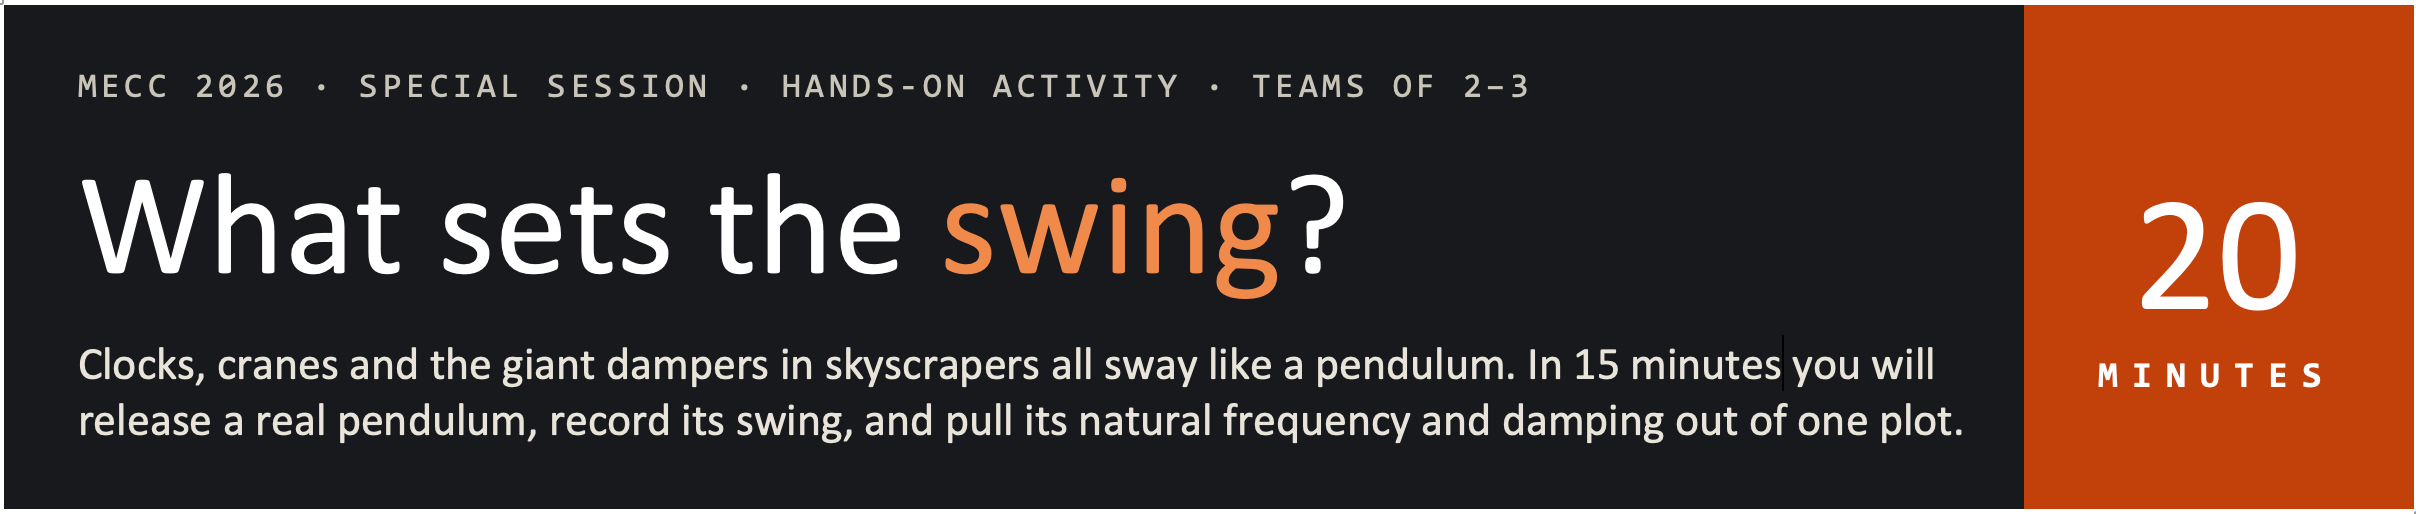

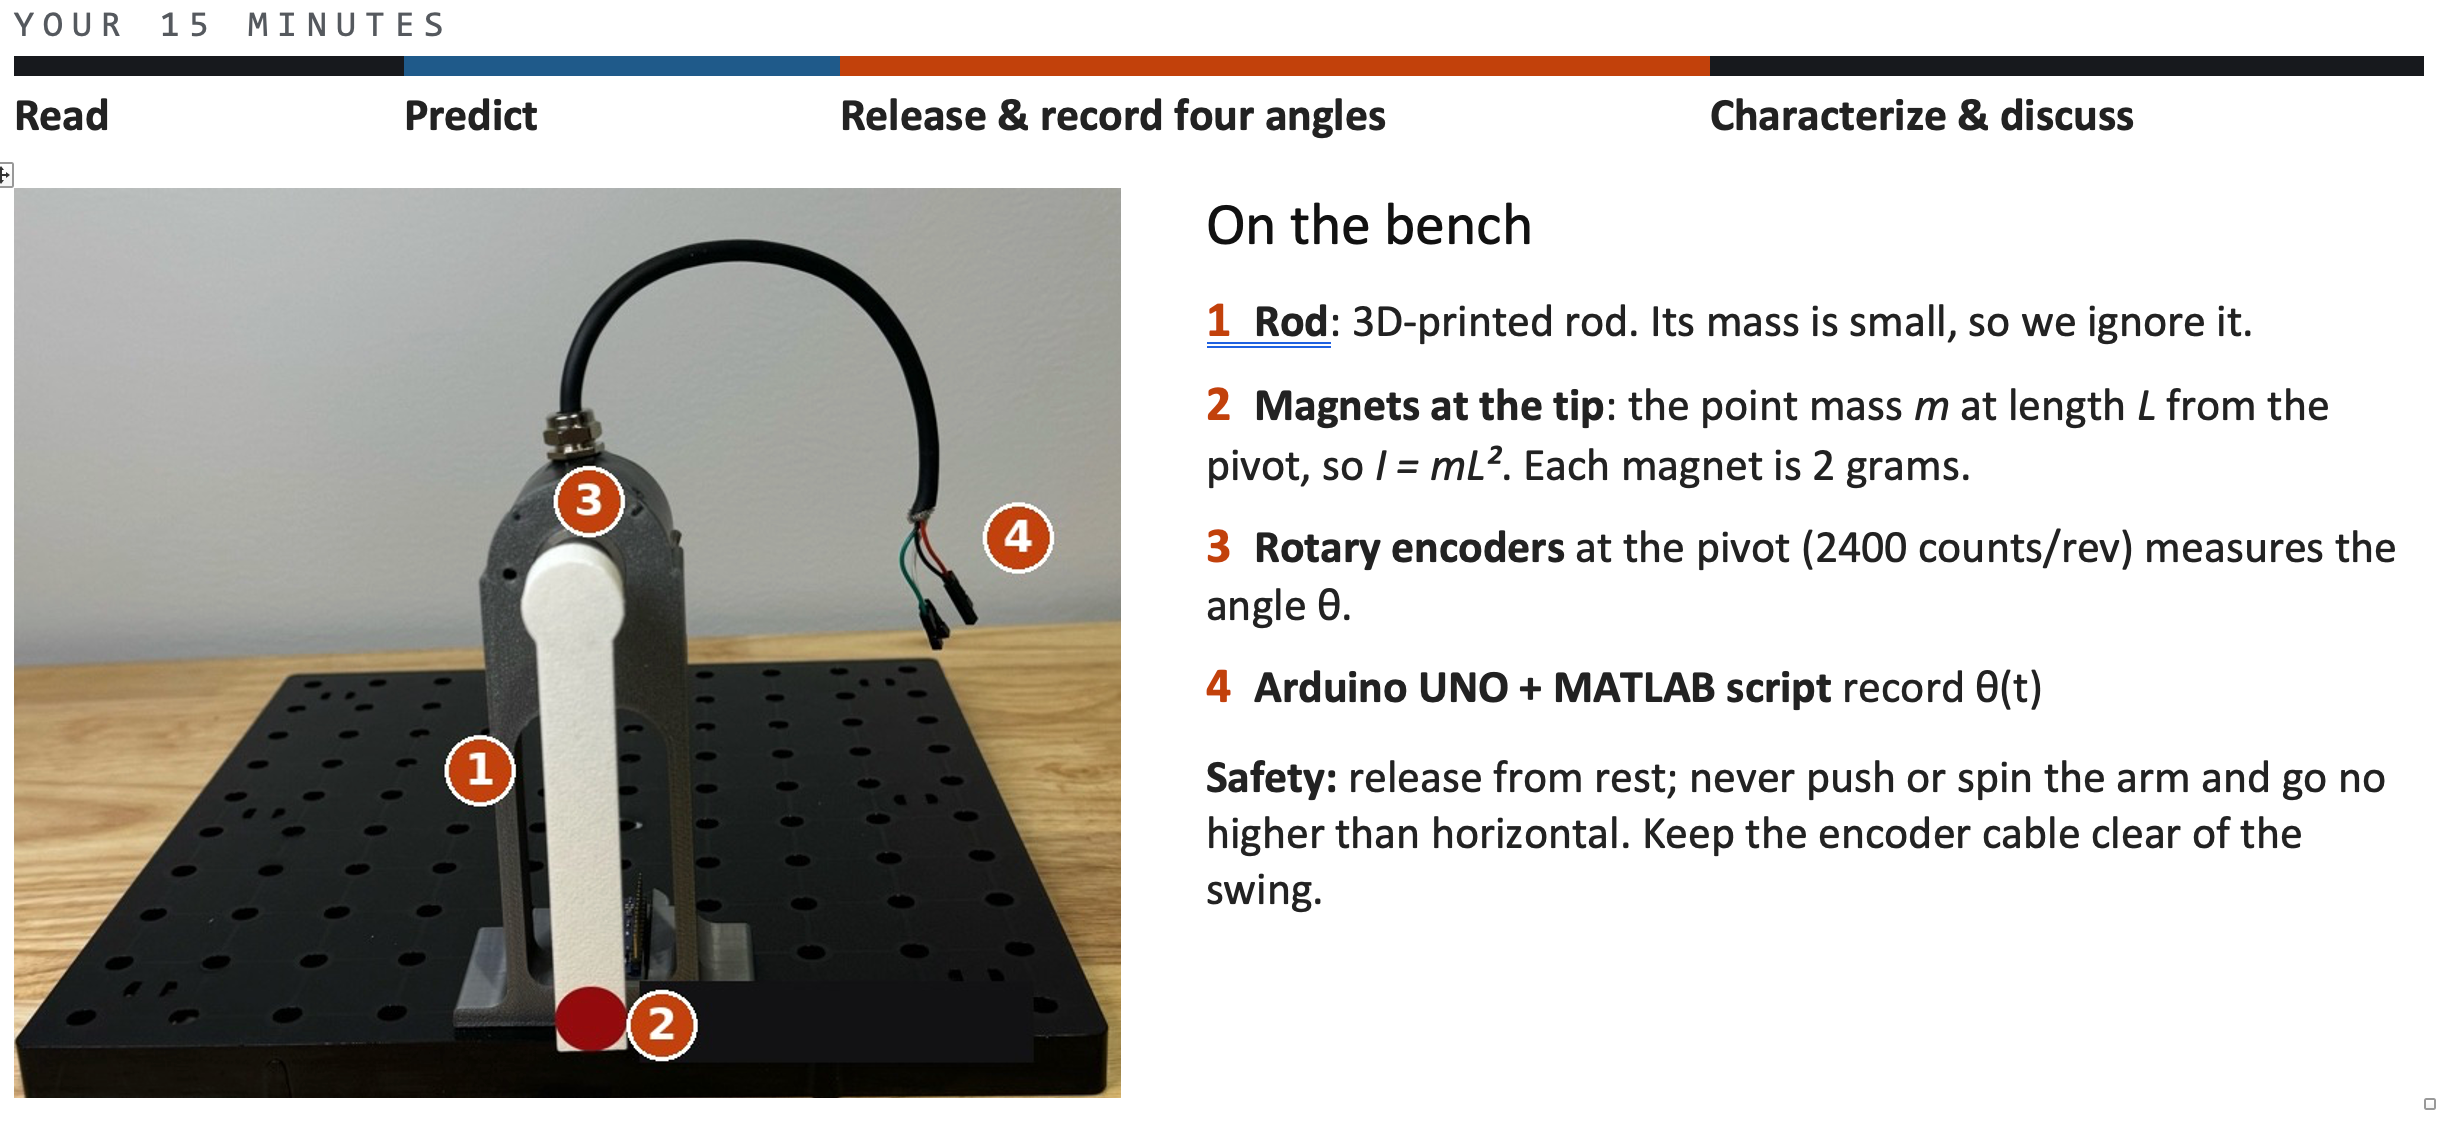

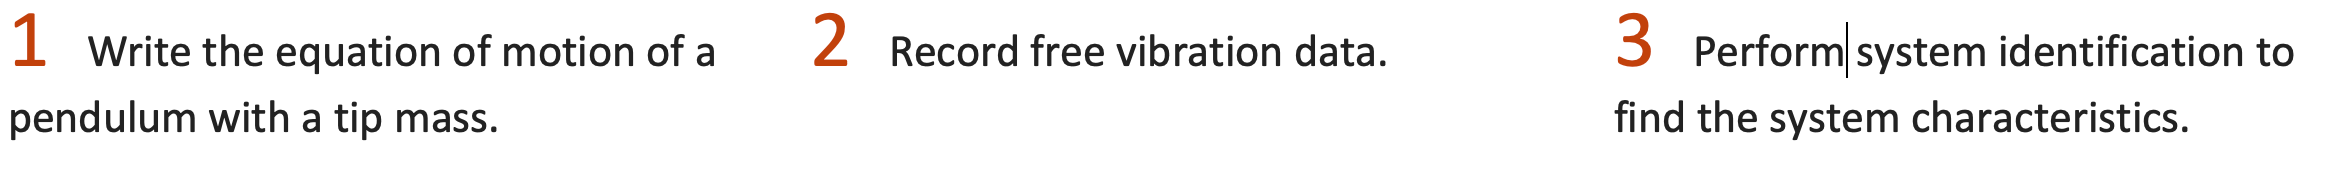

## The key idea

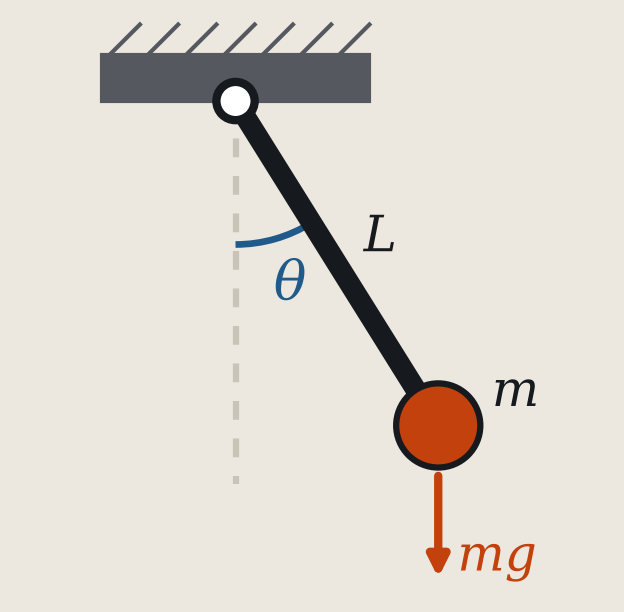

**Equation of motion (moments about the pivot):**


$$mL^2 \ddot{\theta} +c_t \dot{\theta} +mgL\sin \theta =0$$


**Small angles,** $\sin \theta \approx \theta$:


$$\ddot{\theta} \left(t\right)+2\zeta \omega_n \dot{\theta} \left(t\right)+\omega_n^2 \theta \left(t\right)=0,\mathrm{or}\;\ddot{\;\theta } \left(t\right)+\frac{c_t }{{\mathrm{mL}}^{2\;} }\dot{\theta} \left(t\right)+\frac{g}{L}\theta \left(t\right)=0$$


Here, $\omega_n =\sqrt{g/L}$.

**Free response:**


$$\theta (t)=\Theta \,e^{-\zeta \omega_n t} \cos (\omega_d t-\phi ),~~~~\omega_d =\omega_n \sqrt{1-\zeta^2 }$$


${m=\mathrm{total}\;\mathrm{mass}\;\mathrm{at}\;\mathrm{the}\;\mathrm{tip},\;c}_t$ = damping torque per unit angular velocity at the pivot (N·m·s/rad).  $I=mL^2$ and the gravity torque $mgL$ both grow with *m*, so $\omega_n =\sqrt{g/L}$.

## Setup: connect to the Arduino

Plug in the Arduino, set the serial port for your laptop, and run this section once. Set **useHardware = false** to try the whole script with simulated data (no pendulum needed).

clear; close all;

useHardware = true;    % false = demo mode with simulated data (no Arduino needed)

SERIAL_PORT = '';   % leave empty to find the Arduino automatically (works with any USB port)
% SERIAL_PORT = '/dev/tty.usbserial-1130';   % or set it by hand (Mac)
% SERIAL_PORT = 'COM3';                      % or set it by hand (Windows)

sampleTime   = 20e-3;   % sampling time (s)
duration     = 10;       % recording time after release (s)
countsPerRev = 2400;    % encoder counts per revolution
g            = 9.81;    % m/s^2

if useHardware
    if isempty(SERIAL_PORT)
        SERIAL_PORT = findArduinoPort();
    end
    fprintf('Using serial port %s. Connecting (this can take up to a minute)...\n', SERIAL_PORT);
    a = arduino(SERIAL_PORT, 'Uno', 'Libraries', 'rotaryEncoder');
    encoder = rotaryEncoder(a, 'D2', 'D3', 400);
    disp('Arduino connected. Let the arm hang still at 0 deg.')
else
    encoder = [];
    disp('Demo mode: data will be simulated.')
end

Serial ports seen: /dev/cu.wlan-debug, /dev/tty.wlan-debug, /dev/cu.debug-console, /dev/tty.debug-console, /dev/cu.JabraEvolve65, /dev/tty.JabraEvolve65, /dev/cu.Bluetooth-Incoming-Port, /dev/tty.Bluetooth-Incoming-Port, /dev/cu.usbserial-2130, /dev/tty.usbserial-2130


Using serial port /dev/tty.usbserial-2130. Connecting (this can take up to a minute)...


Arduino connected. Let the arm hang still at 0 deg.


## Predict

Measure your pendulum and enter the values below (rod mass ignored). Before you run anything, discuss as a team:

*If you doubled the tip mass m, would the pendulum swing faster, slower, or at the same rate? Why?*  Your prediction: ______________________

m = 8e-3;    % tip mass (kg)                        <-- EDIT
L = 10e-2;    % length, pivot to magnet centre (m)   <-- EDIT
g=9.81;

I = m*L^2;                       % moment of inertia about the pivot (kg*m^2)

% Model prediction (step 3 of "Model it")
wn_model = sqrt(g/L);            % rad/s
fn_model = wn_model/(2*pi);      % Hz
Tn_model = 1/fn_model;           % s


fprintf('I  = m*L^2      = %.5f kg*m^2\n', I);

I  = m*L^2      = 0.00008 kg*m^2


fprintf('wn = sqrt(g/L)  = %.3f rad/s\n', wn_model);

wn = sqrt(g/L)  = 9.905 rad/s


fprintf('fn = wn/(2*pi)  = %.3f Hz\n',    fn_model);

fn = wn/(2*pi)  = 1.576 Hz


fprintf('Tn = 1/fn       = %.3f s\n',     Tn_model);

Tn = 1/fn       = 0.634 s


## **Data Collection**

## Release & record: Setup A (small angle, about 15°)

Run this section. When you see **"Start moving the pendulum..."**, rotate the arm from 0° to about **15°**, hold it still, and release. Recording starts automatically when the arm is released and lasts 5 s.

runA = recordSwing(encoder, 'A', 15, duration, sampleTime, countsPerRev, L);

Setup A: lift the pendulum to about 15 deg, hold still, then release.
Setup A recorded: 392 samples over 10.0 s.


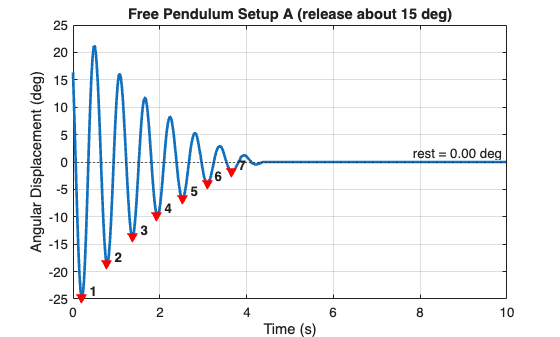

pkA  = findSwingPeaks(runA);
plotSwing(runA, pkA);

## Setup B (about 30°)

Same procedure: release from about **30°**.

runB = recordSwing(encoder, 'B', 30, duration, sampleTime, countsPerRev, L);

Setup B: lift the pendulum to about 30 deg, hold still, then release.
Setup B recorded: 392 samples over 10.0 s.


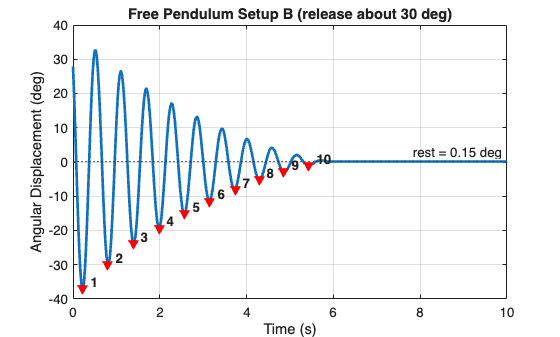

pkB  = findSwingPeaks(runB);
plotSwing(runB, pkB);

## Setup C (about 60°)

Release from about **60°**.

runC = recordSwing(encoder, 'C', 60, duration, sampleTime, countsPerRev, L);

Setup C: lift the pendulum to about 60 deg, hold still, then release.
Setup C recorded: 397 samples over 10.0 s.


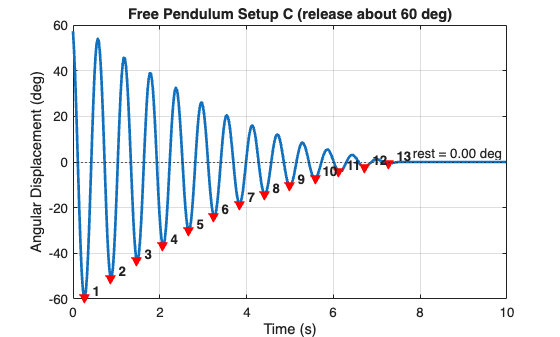

pkC  = findSwingPeaks(runC);
plotSwing(runC, pkC);

## Setup D (about 90°, horizontal; no higher)

Release from about **90°**. Do not go above horizontal.

runD = recordSwing(encoder, 'D', 90, duration, sampleTime, countsPerRev, L);

Setup D: lift the pendulum to about 90 deg, hold still, then release.
Setup D recorded: 387 samples over 10.0 s.


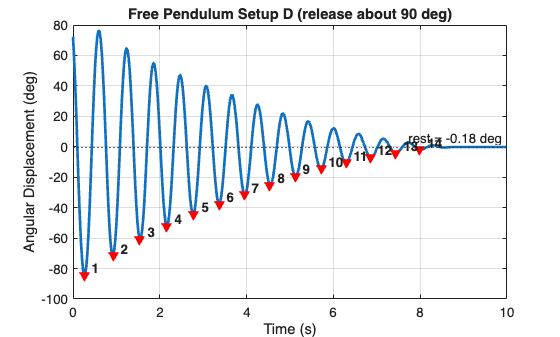

pkD  = findSwingPeaks(runD);
plotSwing(runD, pkD);

## 4  Characterize the pendulum (Setup A)

Use the small-angle run. On the plot, each peak is numbered and measured from the final rest angle (so it still works if the trace doesn't settle exactly at 0°). Pick two peaks **n cycles apart, early in the decay**, and enter them below. The table lists every detected peak.

disp(pkA)

    Peak    Time_s     Theta_deg
    ____    _______    _________

     1      0.20111      24.75  
     2      0.77651       18.6  
     3       1.3791      13.65  
     4       1.9345       9.75  
     5       2.5293        6.6  
     6        3.094        3.9  
     7       3.6511        1.8  




firstPeak = 1;    % number of the first peak you picked    <-- EDIT
n         = 3;    % how many cycles later the second peak is <-- EDIT

if firstPeak + n > height(pkA)
    error('Only %d peaks detected: choose a smaller n or an earlier firstPeak.', height(pkA));
end
theta1  = pkA.Theta_deg(firstPeak);      t1  = pkA.Time_s(firstPeak);
thetaN1 = pkA.Theta_deg(firstPeak+n);    tN1 = pkA.Time_s(firstPeak+n);
fprintf('theta_1   = %6.2f deg   at t_1   = %.3f s\n', theta1,  t1);

theta_1   =  24.75 deg   at t_1   = 0.201 s


fprintf('theta_n+1 = %6.2f deg   at t_n+1 = %.3f s   (n = %d cycles)\n', thetaN1, tN1, n);

theta_n+1 =   9.75 deg   at t_n+1 = 1.935 s   (n = 3 cycles)


Now find the system parameters:


$$\delta =\frac{1}{n}\ln \frac{\theta_1 }{\theta_{n+1} },~~\zeta =\frac{\delta }{\sqrt{4\pi^2 +\delta^2 }},~~T_d =\frac{t_{n+1} -t_1 }{n},~~\omega_d =\frac{2\pi }{T_d },~~\omega_n =\frac{\omega_d }{\sqrt{1-\zeta^2 }},~~c_t =2\zeta mL^2 \omega_n$$


delta = (1/n)*log(theta1/thetaN1);       % logarithmic decrement
zeta  = delta/sqrt(4*pi^2 + delta^2);    % damping ratio
Td    = (tN1 - t1)/n;                    % damped period (s)
wd    = 2*pi/Td;                         % damped natural frequency (rad/s)
wn    = wd/sqrt(1 - zeta^2);             % natural frequency (rad/s)
ct    = 2*zeta*m*L^2*wn;                 % damping coefficient (N*m*s/rad)

Parameter = ["delta"; "zeta"; "T_d"; "omega_d"; "omega_n"; "c_t"];
Value     = [delta; zeta; Td; wd; wn; ct];
Units     = ["-"; "-"; "s"; "rad/s"; "rad/s"; "N*m*s/rad"];
results   = table(Parameter, Value, Units)

results = 6×3 table
    Parameter      Value          Units   
    _________    __________    ___________

    "delta"         0.31052    "-"        
    "zeta"          0.04936    "-"        
    "T_d"           0.57781    "s"        
    "omega_d"        10.874    "rad/s"    
    "omega_n"        10.887    "rad/s"    
    "c_t"        8.5985e-05    "N*m*s/rad"


**Check:** the measured parameters rebuild the free response $\theta (t)=\theta_1 e^{-\zeta \omega_n (t-t_1 )} \cos (\omega_d (t-t_1 ))$. Does the dashed model line sit on your data?

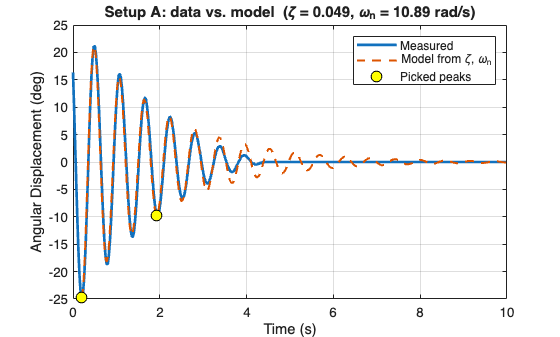

tm = linspace(t1, runA.t(end), 600);
thModel = pkA.Properties.UserData.rest + pkA.Properties.UserData.sign * ...
          theta1*exp(-zeta*wn*(tm - t1)).*cos(wd*(tm - t1));

figure;
plot(runA.t, runA.theta, 'LineWidth', 2); hold on;
plot(tm, thModel, '--', 'LineWidth', 1.5);
plot([t1 tN1], pkA.Properties.UserData.rest + pkA.Properties.UserData.sign*[theta1 thetaN1], ...
     'ko', 'MarkerFaceColor', 'y', 'MarkerSize', 8);
xlabel('Time (s)'); ylabel('Angular Displacement (deg)');
title(sprintf('Setup A: data vs. model  (\\zeta = %.3f, \\omega_n = %.2f rad/s)', zeta, wn));
legend('Measured', 'Model from \zeta, \omega_n', 'Picked peaks'); grid on;

## 5  Model it

**1.** On your handout sketch, draw the free-body diagram of the arm. Label the gravity force, the pivot reaction and the damping torque.

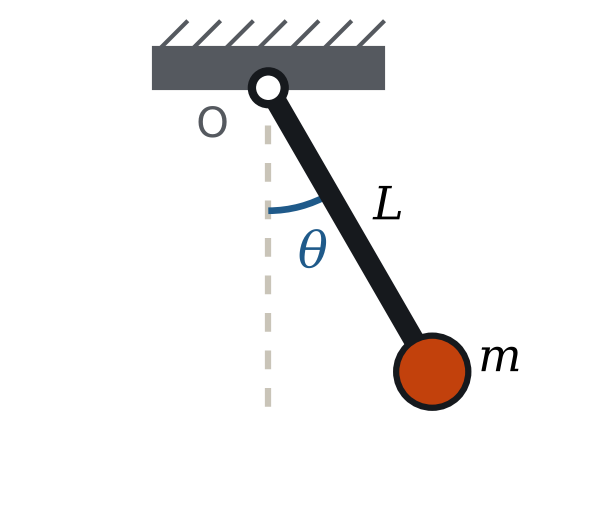

**2.** Sum moments about the pivot O to get the equation of motion in section 1.

**3.** Predict from the model using your measured *L* (computed in section 2), and compare with the measurement:

pctDiff = abs(wn - wn_model)/wn_model*100;

Quantity = ["omega_n (rad/s)"; "f_n (Hz)"; "T_n (s)"];
Model    = [wn_model; fn_model; Tn_model];
Measured = [wn; wn/(2*pi); 2*pi/wn];
comparison = table(Quantity, Model, Measured)

comparison = 3×3 table
        Quantity          Model     Measured
    _________________    _______    ________

    "omega_n (rad/s)"     9.9045     10.887 
    "f_n (Hz)"            1.5764     1.7328 
    "T_n (s)"            0.63437    0.57711 


fprintf('Measured omega_n differs from sqrt(g/L) by %.1f %%\n', pctDiff);

Measured omega_n differs from sqrt(g/L) by 9.9 %


**4.** Where did $\sin \theta \approx \theta$ come in, and from which of setups A–D would you stop trusting it? Check against your observed periods below.

allRuns = {}; allPk = {};
if exist('runA','var'), allRuns{end+1} = runA; allPk{end+1} = pkA; end
if exist('runB','var'), allRuns{end+1} = runB; allPk{end+1} = pkB; end
if exist('runC','var'), allRuns{end+1} = runC; allPk{end+1} = pkC; end
if exist('runD','var'), allRuns{end+1} = runD; allPk{end+1} = pkD; end

k = numel(allRuns);
Setup = strings(k,1); Amplitude_deg = nan(k,1); Period_meas_s = nan(k,1); Period_large_s = nan(k,1);
for j = 1:k
    pk = allPk{j};
    Setup(j)         = allRuns{j}.label;
    Amplitude_deg(j) = pk.Theta_deg(1);
    if height(pk) >= 2
        Period_meas_s(j) = mean(diff(pk.Time_s(1:min(3,end))));   % early cycles
    end
    th0 = deg2rad(Amplitude_deg(j));
    Period_large_s(j) = Tn_model*(1 + th0^2/16 + 11*th0^4/3072);  % large-angle correction
end
Period_small_s = repmat(Tn_model, k, 1);
periods = table(Setup, Amplitude_deg, Period_meas_s, Period_small_s, Period_large_s)

periods = 4×5 table
    Setup    Amplitude_deg    Period_meas_s    Period_small_s    Period_large_s
    _____    _____________    _____________    ______________    ______________

     "A"         24.75           0.58901          0.63437           0.64185    
     "B"          37.2           0.58026          0.63437           0.65149    
     "C"         59.55           0.59923          0.63437           0.67985    
     "D"        84.119           0.64157          0.63437           0.73039    


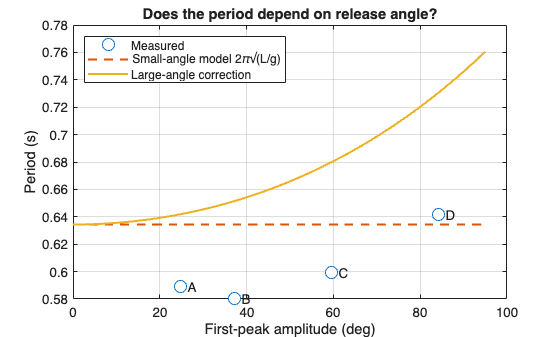


figure;
plot(Amplitude_deg, Period_meas_s, 'o', 'MarkerSize', 9, 'MarkerFaceColor', 'auto'); hold on;
a0 = linspace(0, 95, 200); r0 = deg2rad(a0);
plot(a0, Tn_model*ones(size(a0)), '--', 'LineWidth', 1.5);
plot(a0, Tn_model*(1 + r0.^2/16 + 11*r0.^4/3072), '-', 'LineWidth', 1.5);
text(Amplitude_deg, Period_meas_s, "  " + Setup);
xlabel('First-peak amplitude (deg)'); ylabel('Period (s)');
legend('Measured', 'Small-angle model 2\pi\surd(L/g)', 'Large-angle correction', 'Location', 'northwest');
title('Does the period depend on release angle?'); grid on;

Your answer: ______________________________________________

**5.** Measured $\omega_n$ vs. $\sqrt{g/L}$ differs by the percentage printed above. Give one reason they disagree. *(Hint: what did we ignore?)*

Your answer: ______________________________________________

## Takeaway

The swing rate comes from geometry, $\omega_n =\sqrt{g/L}$; the decay comes from damping. One free-release plot gives you both.

if useHardware
    clear encoder a      % release the serial port
end

## Helper functions

These run behind the scenes. You don't need to edit them.

function run = recordSwing(encoder, label, releaseAngle, duration, sampleTime, countsPerRev, L)
% Waits for the arm to be lifted and released, then records theta(t) for DURATION seconds.
nMax  = ceil(duration/sampleTime) + 1;
t     = nan(nMax, 1);
theta = nan(nMax, 1);

if ~isempty(encoder)
    resetCount(encoder);                              % arm hanging at rest = 0 deg
    readAngle = @() double(readCount(encoder))/countsPerRev*360;
    msg = sprintf('Setup %s: lift the pendulum to about %g deg, hold still, then release.', label, releaseAngle);
    fprintf('%s\n', msg);

    % Pop-up prompt window with a live angle readout (always visible, even if the Live Editor lags)
    fig = figure('Name', 'Pendulum: data collection', 'NumberTitle', 'off', ...
                 'MenuBar', 'none', 'ToolBar', 'none', 'Color', 'w', 'Position', [300 300 560 220]);
    uicontrol(fig, 'Style', 'text', 'Units', 'normalized', 'Position', [0.05 0.50 0.90 0.42], ...
              'String', msg, 'FontSize', 16, 'FontWeight', 'bold', 'BackgroundColor', 'w');
    hAng = uicontrol(fig, 'Style', 'text', 'Units', 'normalized', 'Position', [0.05 0.10 0.90 0.32], ...
              'String', 'Current angle: 0.0 deg', 'FontSize', 22, 'ForegroundColor', [0 0.45 0.74], ...
              'BackgroundColor', 'w');
    figure(fig); drawnow;

    % Wait for release: arm lifted past 5 deg, then moving back from its highest point
    tWait = tic; peak = 0;
    while true
        th = readAngle();
        if abs(th) > abs(peak), peak = th; end
        if abs(peak) > 5 && abs(th) < abs(peak) - 1.5, break; end
        if isvalid(hAng)
            hAng.String = sprintf('Current angle: %.1f deg', th);
            drawnow limitrate;
        end
        if toc(tWait) > 60
            warning('No release detected after 60 s; recording anyway.'); break;
        end
    end
    if isvalid(fig)
        hAng.String = 'Released! Recording...';
        hAng.ForegroundColor = [0 0.6 0];
        drawnow;
    end

    % Record every sampleTime
    i = 1; t0 = tic;
    while toc(t0) <= duration && i <= nMax
        t(i)     = toc(t0);
        theta(i) = readAngle();
        while toc(t0) <= i*sampleTime   % wait for the next sample time
        end
        i = i + 1;
    end
    keep = ~isnan(t); t = t(keep); theta = theta(keep);
    if isvalid(fig), close(fig); end
else
    % Demo mode: simulate a nonlinear, lightly damped pendulum (slightly "longer" than L)
    Leff = 1.04*L; wnS = sqrt(9.81/Leff); zS = 0.02;
    f  = @(tt, x) [x(2); -2*zS*wnS*x(2) - wnS^2*sin(x(1))];
    t  = (0:sampleTime:duration)';
    [~, X] = ode45(f, t, [deg2rad(releaseAngle); 0]);
    res = 360/countsPerRev;
    theta = round((rad2deg(X(:,1)) + 0.4)/res)*res;   % encoder quantization + small offset
end
fprintf('Setup %s recorded: %d samples over %.1f s.\n', label, numel(t), t(end));
run = struct('label', string(label), 'releaseAngle', releaseAngle, 't', t, 'theta', theta);
end

function port = findArduinoPort()
% Finds the Arduino's serial port, whichever USB socket the cable is plugged into.
ports = serialportlist("all");
fprintf('Serial ports seen: %s\n', strjoin(ports, ', '));
if ismac
    cand = ports(contains(ports, "/dev/tty.") & contains(ports, ["usbserial", "usbmodem"]));
elseif ispc
    cand = ports(startsWith(ports, "COM"));
else
    cand = ports(contains(ports, ["ttyUSB", "ttyACM"]));
end
if isempty(cand)
    error(['No Arduino port found. Unplug and replug the USB cable, close the Arduino IDE, ' ...
           'and run this section again.']);
end
if numel(cand) > 1
    warning('Several possible ports (%s). Using %s. If it fails, set SERIAL_PORT by hand.', ...
            strjoin(cand, ', '), cand(1));
end
port = char(cand(1));
end

function pk = findSwingPeaks(run)
% Finds peaks on the release side, measured from the final rest angle.
th    = run.theta(:); t = run.t(:);
nTail = max(1, round(0.15*numel(th)));
rest  = mean(th(end-nTail+1:end));                   % final rest angle
x     = th - rest;
[~, iMax] = max(abs(x));  s = sign(x(iMax)); if s == 0, s = 1; end
x     = s*x;                                         % release side positive
isPk  = islocalmax(x, 'MinProminence', 0.5, 'FlatSelection', 'center') & x > 0.5;
idx   = find(isPk);
Peak  = (1:numel(idx))';
Time_s    = t(idx);
Theta_deg = x(idx);
pk = table(Peak, Time_s, Theta_deg);
pk.Properties.UserData = struct('rest', rest, 'sign', s);
if height(pk) < 2
    warning('Fewer than 2 peaks found. Re-run the setup and release from rest.');
end
end

function plotSwing(run, pk)
figure;
plot(run.t, run.theta, 'LineWidth', 2); hold on;
rest = pk.Properties.UserData.rest; s = pk.Properties.UserData.sign;
yline(rest, ':', sprintf('rest = %.2f deg', rest));
yPk = rest + s*pk.Theta_deg;
plot(pk.Time_s, yPk, 'v', 'MarkerFaceColor', 'r', 'MarkerEdgeColor', 'r');
text(pk.Time_s, yPk, "  " + string(pk.Peak), 'VerticalAlignment', 'bottom', 'FontWeight', 'bold');
xlabel('Time (s)'); ylabel('Angular Displacement (deg)');
title(sprintf('Free Pendulum Setup %s (release about %g deg)', run.label, run.releaseAngle));
grid on;
end
